BL.AI.U4AID25064

Sudarshan Rao

Lab Exercise - 5

% example - 1

A = [3,0,1;0,4,2;1,2,3];
b = [3;0;1];
x0 = randi([-9,9],length(b),1);
% x0 = [0;0;0];
r0 = b - A*x0

r0 =      7
    42
    35


d0 = r0;
rsold = r0'*r0;

history  = x0'

history =      1    -7    -7


for i = 1:length(b)
    Ad = A * d0;
    alpha = rsold / (d0' * Ad);
    x0 = x0 + alpha * d0;
    history(end+1, :) = x0';
    r0 = r0 - alpha * Ad;
    rsnew = r0'*r0;

    if sqrt(rsnew) < 1e-10
        break;
    end

    d0 = r0 + (rsnew / rsold) * d0;
    rsold = rsnew;
end

x0

x0 =     1.0000
    0.0000
    0.0000


residue = b - A*x0

residue = 1.0e-14 *

   -0.1776
   -0.5773
   -0.4663


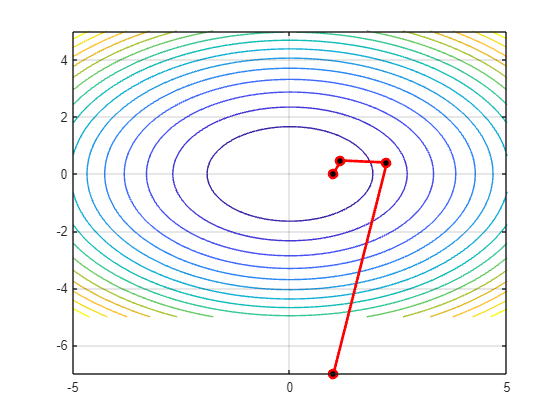


[X, Y] = meshgrid(-5:0.1:5, -5:0.1:5);

% 2. Calculate the matrix surface surface values
Z = 0.5 * (A(1,1)*X.^2 + (A(1,2)+A(2,1))*X.*Y + A(2,2)*Y.^2);

% 3. Plot the matrix contours
figure;
contour(X, Y, Z, 15);
hold on;
grid on;
plot(history(:, 1), history(:, 2), '-ro', 'LineWidth', 2, 'MarkerFaceColor', 'k');

% example - 2

A = [5,1,2,-1;1,9,1,3;2,1,4,0;-1,3,0,6];
b = [7;14;7;8];
x0 = randi([-9,9],length(b),1);

r0 = b - A*x0

r0 =    -12
   -39
    15
    -5


d0 = r0;
rsold = r0'*r0;

history  = x0'

history =      5     6    -6     0


for i = 1:length(b)
    Ad = A * d0;
    alpha = rsold / (d0' * Ad);
    x0 = x0 + alpha * d0;
    history(end+1, :) = x0';
    r0 = r0 - alpha * Ad;
    rsnew = r0'*r0;

    if sqrt(rsnew) < 1e-10
        break;
    end

    d0 = r0 + (rsnew / rsold) * d0;
    rsold = rsnew;
end

x0

x0 =     1.0000
    1.0000
    1.0000
    1.0000


residue = b - A*x0

residue = 1.0e-13 *

    0.0178
    0.1066
    0.0178
    0.0533


% example - 3

A = [4,2;2,2];
b = [-1;1];
x0 = randi([-9,9],length(b),1);

r0 = b - A*x0

r0 =     -3
    -3


d0 = r0;
rsold = r0'*r0;

history  = x0'

history =     -1     3


for i = 1:length(b)
    Ad = A * d0;
    alpha = rsold / (d0' * Ad);
    x0 = x0 + alpha * d0;
    history(end+1, :) = x0';
    r0 = r0 - alpha * Ad;
    rsnew = r0'*r0;

    if sqrt(rsnew) < 1e-10
        break;
    end

    d0 = r0 + (rsnew / rsold) * d0;
    rsold = rsnew;
end

x0

x0 =    -1.0000
    1.5000


residue = b - A*x0

residue = 1.0e-15 *

   -0.8882
   -0.6661


practise questions

% question - 1

clc
clear

A = [9 2;
     2 9];

n = size(A,1);

D = zeros(n);

D(:,1) = [1;0];

for k = 2:n

    v = zeros(n,1);
    v(k) = 1;

    for j = 1:k-1
        beta = (D(:,j)'*A*v)/(D(:,j)'*A*D(:,j));
        v = v - beta*D(:,j);
    end

    D(:,k) = v;

end

disp("A-Conjugate Directions")

A-Conjugate Directions


disp(D)

    1.0000   -0.2222
         0    1.0000



% question - 2

clc
clear

A = [8 2 1;
     2 7 2;
     1 2 5];

n = size(A,1);

D = zeros(n);

D(:,1) = [1;0;0];

for k = 2:n

    v = zeros(n,1);
    v(k)=1;

    for j=1:k-1
        beta=(D(:,j)'*A*v)/(D(:,j)'*A*D(:,j));
        v=v-beta*D(:,j);
    end

    D(:,k)=v;

end

disp(D)

    1.0000   -0.2500   -0.0577
         0    1.0000   -0.2692
         0         0    1.0000



% question - 3
% a

clc
clear

A = [2 1 -1;
     1 2 -1;
    -1 -1 4];

b = [1;2;9];

x0 = randi([-9 9],3,1);

r0 = b - A*x0;
d0 = r0;
rsold = r0'*r0;

history = x0';

for i=1:length(b)

    Ad = A*d0;

    alpha = rsold/(d0'*Ad);

    x0 = x0 + alpha*d0;

    history(end+1,:) = x0';

    r0 = r0 - alpha*Ad;

    rsnew = r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0 = r0 + (rsnew/rsold)*d0;

    rsold = rsnew;

end

x0

x0 =     1.0000
    2.0000
    3.0000



residue = b-A*x0

residue = 1.0e-14 *

   -0.3109
   -0.5773
    0.7105


% question - 3
% b
clc
clear

A = [1 1 2;
     1 2 4;
     2 4 6];

b = [1;2;17];

x0 = randi([-9 9],3,1);

r0 = b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:length(b)

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

residue=b-A*x0

% question - 3
% c
clc
clear

A = [3 0 1;
     0 4 2;
     1 2 3];

b = [3;0;1];

x0=randi([-9 9],3,1);

r0=b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:length(b)

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     1.0000
    0.0000
   -0.0000



residue=b-A*x0

residue = 1.0e-14 *

    0.3109
   -0.0888
    0.4219


% question - 4
% a
clc
clear

H = [8 0;
     0 6];

c = [16;36];

A = H;
b = c;

x0 = [0;0]; 


r0 = b-A*x0;
d0 = r0;
rsold = r0'*r0;

history = x0';

for i=1:2

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =      2
     6



history

history =          0         0
    2.5277    5.6873
    2.0000    6.0000


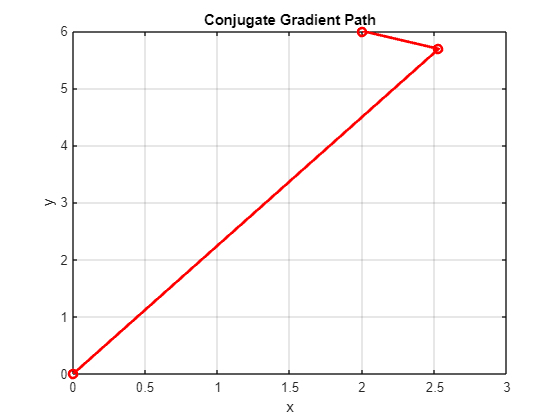


figure

plot(history(:,1),history(:,2),'ro-','LineWidth',2)

grid on

xlabel('x')

ylabel('y')

title('Conjugate Gradient Path')

% question - 4
% c
clc
clear

H = [8 0;
     0 6];

c = [16;36];

A = H;
b = c;

x0 = [50;0];

r0 = b-A*x0;
d0 = r0;
rsold = r0'*r0;

history = x0';

for i=1:2

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     2.0000
    6.0000



history

history =    50.0000         0
    1.8952    4.5098
    2.0000    6.0000


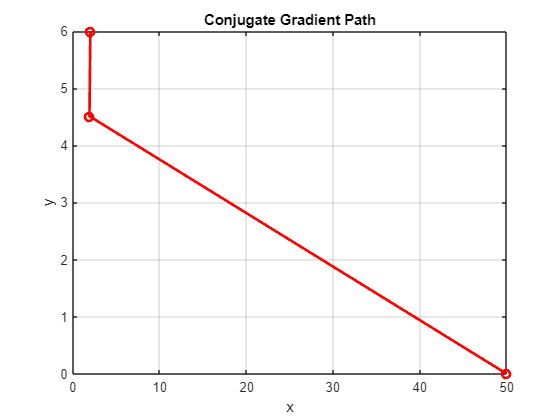


figure

plot(history(:,1),history(:,2),'ro-','LineWidth',2)

grid on

xlabel('x')

ylabel('y')

title('Conjugate Gradient Path')

% question - 4
% d
clc
clear

H = [8 0;
     0 6];

c = [16;36];

A = H;
b = c;

x0 = [0;-25];      % Change here

r0 = b-A*x0;
d0 = r0;
rsold = r0'*r0;

history = x0';

for i=1:2

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     2.0000
    6.0000



history

history =          0  -25.0000
    2.6602    5.9243
    2.0000    6.0000


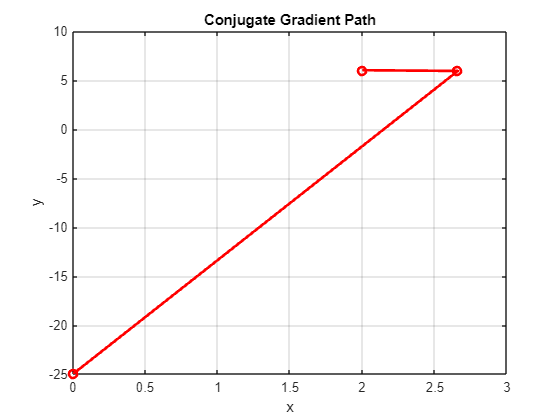


figure

plot(history(:,1),history(:,2),'ro-','LineWidth',2)

grid on

xlabel('x')

ylabel('y')

title('Conjugate Gradient Path')

% question - 4
% e
clc
clear

H = [8 0;
     0 6];

c = [16;36];

A = H;
b = c;

x0 = [-21;35];      % Change here

r0 = b-A*x0;
d0 = r0;
rsold = r0'*r0;

history = x0';

for i=1:2

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     2.0000
    6.0000



history

history =   -21.0000   35.0000
    5.0778   10.3395
    2.0000    6.0000


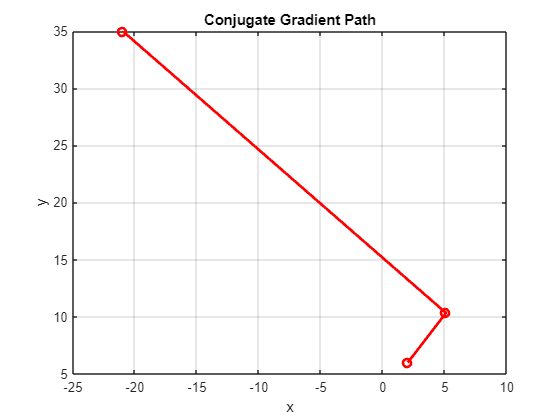


figure

plot(history(:,1),history(:,2),'ro-','LineWidth',2)

grid on

xlabel('x')

ylabel('y')

title('Conjugate Gradient Path')

% question - 5
% a
clc
clear

A=[12 0 2;
   0 16 4;
   2 4 2];

b=[3;0;3];

x0=randi([-9 9],3,1);

r0=b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:length(b)

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =    -0.3750
   -0.9375
    3.7500



residue=b-A*x0

residue = 1.0e-13 *

   -0.2487
   -0.1421
   -0.0622


% question - 5
% b
A=[18 0 0;
   0 10 0;
   0 0 6];

b=[36;-30;8];
x0=randi([-9 9],3,1);

r0=b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:length(b)

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     2.0000
   -3.0000
    1.3333



residue=b-A*x0

residue =      0
     0
     0


% question - 6
a=23;
b1=17;
c=11;

x0=[a;
    b1;
    c;
    b1;
    a];

A=[9 1 1 5 0;
   1 0 1 0 3;
   0 0 0 2 0;
   0 0 0 0 2;
   0 4 2 2 6];

b=[1;18;4;6;10];
r0=b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:length(b)

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     1.1009
  -17.4029
   18.6713
    0.9216
    4.5073



residue=b-A*x0

residue =   -14.7850
  -15.2940
    2.1568
   -3.0145
   13.3820


% question - 7
clc
clear

n=9;

R=randi([1 9],n);

A=R+R';

A=A+n*eye(n);

x=[1:9]';

b=A*x;

x0=randi([-9 9],n,1);

r0=b-A*x0;
d0=r0;
rsold=r0'*r0;

history=x0';

for i=1:n

    Ad=A*d0;

    alpha=rsold/(d0'*Ad);

    x0=x0+alpha*d0;

    history(end+1,:)=x0';

    r0=r0-alpha*Ad;

    rsnew=r0'*r0;

    if sqrt(rsnew)<1e-10
        break
    end

    d0=r0+(rsnew/rsold)*d0;

    rsold=rsnew;

end

x0

x0 =     1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000
    8.0000
    9.0000



iterations=i

iterations = 9


residue=b-A*x0

residue = 1.0e-06 *

   -0.4191
   -0.3023
   -0.3425
   -0.3552
   -0.3934
   -0.3275
   -0.3546
   -0.3082
   -0.3970
